Alejandro Armenta Arellano 

A017348789

Hacemos limpieza de variables y cerramos todo

clear all
close all
clc

Inicializamos las matrices de transformacion para los movimientos y declaramos las posicion inicial 

H0=SE3;
H1=SE3(rotx(pi), [2 0 8]);
H2=SE3(rotx(-pi/2), [0 0 0]);
H3=SE3(roty(-pi/2), [0 0 0]);
H4=SE3(rotz(-pi/2), [0 0 0]);
H5=SE3(rotz(0), [4 0 0]);
H6=SE3(rotz(pi/2), [4 0 0]);
H7=SE3(rotx(pi/2), [0 0 0]);
H8=SE3(roty(pi/2), [0 0 0]);
H9=SE3(rotx(0), [0 0 3]);

convertimos los movimientos realizados en variables para unirlos con posiciones anteriores

H20= H1*H2;
H30= H20*H3;
H40= H30*H4;
H50= H40*H5;

Generamos el plano para las graficas 

plot3(0, 0, 0);
axis([-1 15 -1 15 -1 15]); grid on;
hold on;

Para finalizar graficamos el punto inical y los movimientos

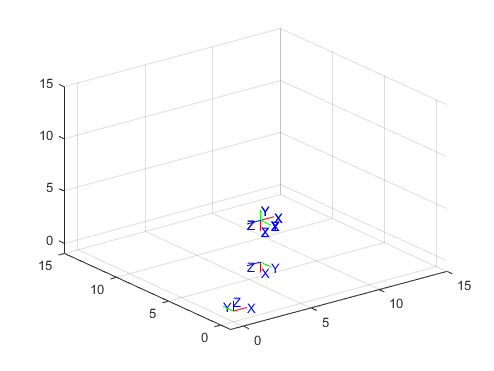

trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])
tranimate(H40, H50,'rgb','axis', [-1 4 -1 6 -1 2])

tranimate(H50, H60,'rgb','axis', [-1 4 -1 6 -1 2])

Unrecognized function or variable 'H60'.

tranimate(H60, H70,'rgb','axis', [-1 4 -1 6 -1 2])
tranimate(H70, H80,'rgb','axis', [-1 4 -1 6 -1 2])
tranimate(H80, H90,'rgb','axis', [-1 4 -1 6 -1 2])
disp(H50)